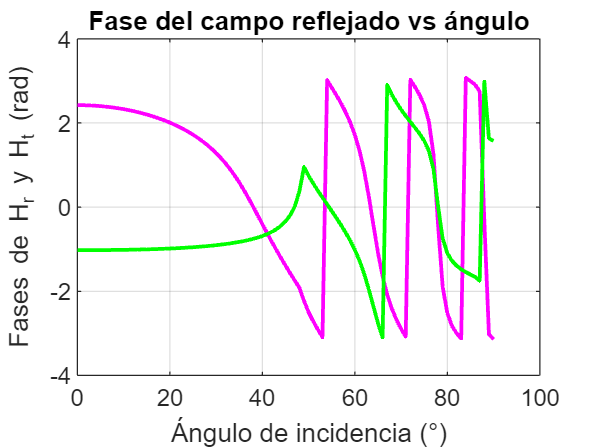

% Rango de ángulos
thetas = 0:1:90;         % en grados
phase_R = zeros(size(thetas));
phase_T = zeros(size(thetas));

n = [4, 5, 3];         % aire -> vidrio -> aire
d = [500e-9,200e-9];            % espesor de la capa
lambda = 600e-9;         % longitud de onda
for k = 1:length(thetas)
    theta_rad = deg2rad(thetas(k));
    [Hr,Ht,~,~,~] = inter(1, theta_rad, n, d, lambda,false);
    phase_R(k) = angle(Hr);
    phase_T(k) = angle(Ht);
end

figure;
plot(thetas, phase_R,'m','LineWidth',1.5);
xlabel('Ángulo de incidencia (°)');
ylabel('Fases de H_r y H_t (rad)');
title('Fase del campo reflejado vs ángulo');
grid on;
hold on;
plot(thetas, phase_T,'m','LineWidth',1.5,Color='g');